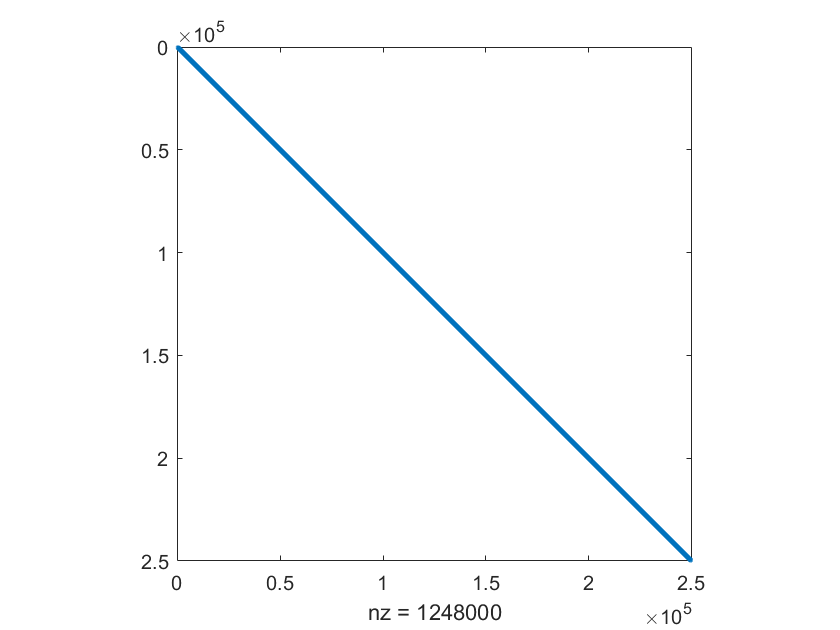

clc;
clf;

load matrix.mat;
spy(A)

[m, n] = size(A);
b = ones(m, 1);
x_init = zeros(n, 1);
tol = 1e-6;
maxit = 1e3;

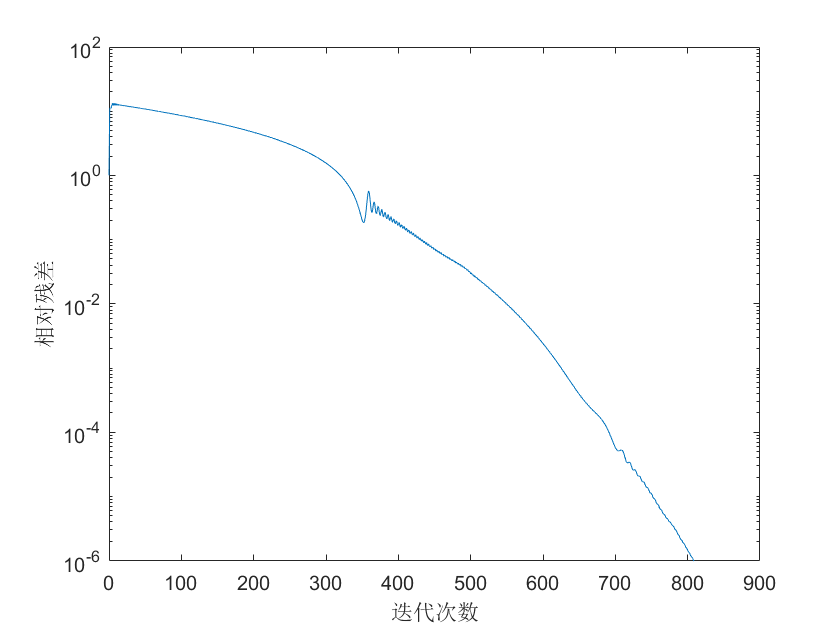

% Without Preconditioner
M = sparse(1:m, 1:n, b);
[x0,relres0,iter0,resvec0] = my_pcg(A,b,tol,maxit,M,x_init);
clf;
semilogy(0:iter0, resvec0/norm(b));
xlabel('迭代次数');
ylabel('相对残差');

## 1. Conjugate Gradient Method with Jacobi Preconditioner:

% jacobi-CG
M = diag(diag(A));      % 在这里等价于没有Precondioner
[x1,relres1,iter1,resvec1] = my_pcg(A,b,tol,maxit,M,x_init);
clf;
semilogy(0:iter1, resvec1/norm(b));
xlabel('迭代次数');
ylabel('相对残差');

## 2. Conjugate Gradient Method with Symmetric successive over-relaxation (SSOR) preconditioner:

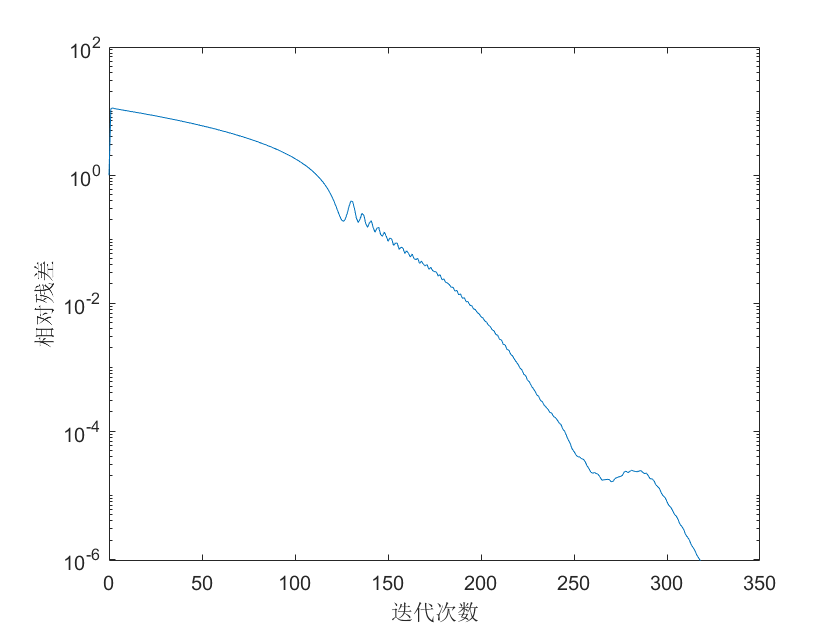

% SSOR-CG
% 0 < lambda < 2
lambda = 1;     % Gauss-Seidel preconditioner
D = diag(diag(A));
D_inv = sparse(1:m, 1:n, 1./diag(A));
L = tril(A)-D;
U = triu(A)-D;
M = (D + lambda * L) * D_inv * (D + lambda * U);
[x2,relres2,iter2,resvec2] = my_pcg(A,b,tol,maxit,M,x_init);
clf;
semilogy(0:iter2, resvec2/norm(b));
xlabel('迭代次数');
ylabel('相对残差');

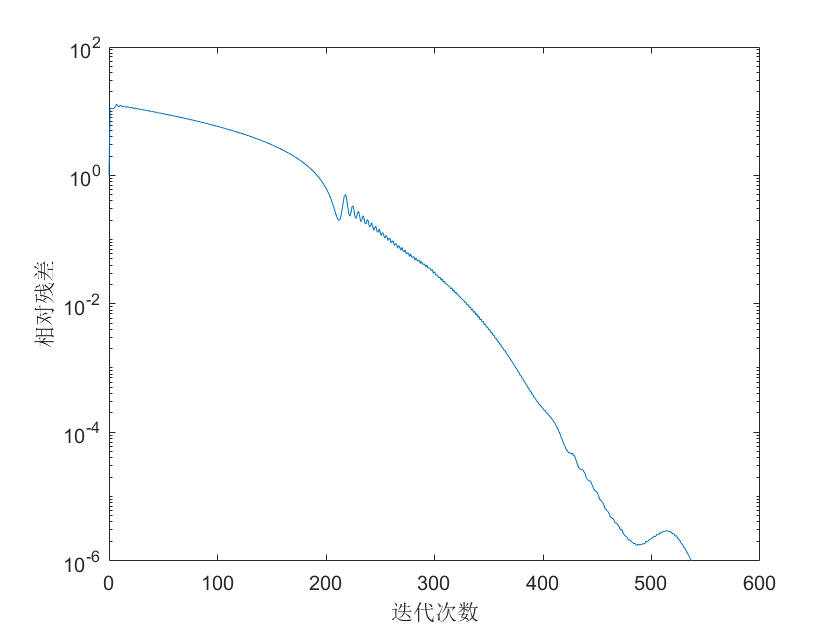

lambda = 0.5;     
D = diag(diag(A));
D_inv = sparse(1:m, 1:n, 1./diag(A));
L = tril(A)-D;
U = triu(A)-D;
M = (D + lambda * L) * D_inv * (D + lambda * U);
[x3,relres3,iter3,resvec3] = my_pcg(A,b,tol,maxit,M,x_init);
clf;
semilogy(0:iter3, resvec3/norm(b));
xlabel('迭代次数');
ylabel('相对残差');

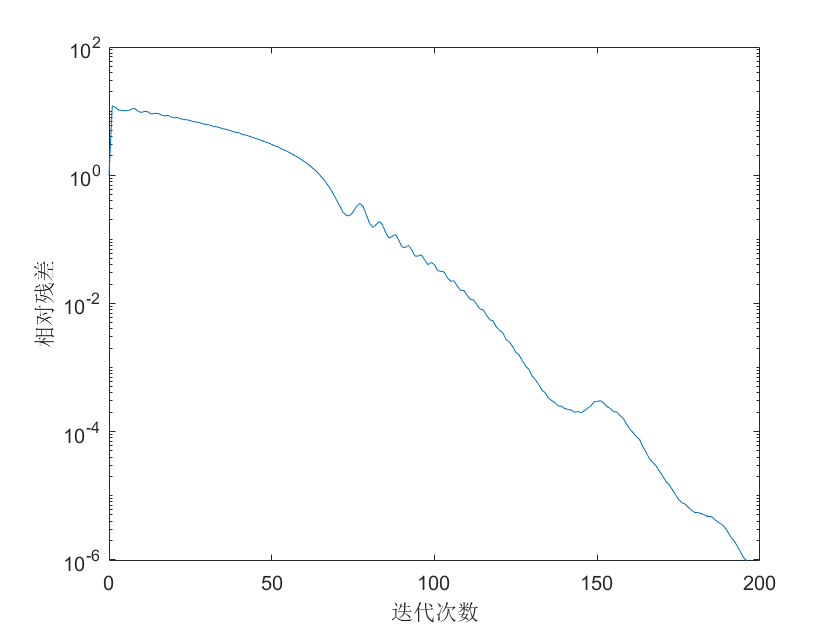

lambda = 1.5;     
D = diag(diag(A));
D_inv = sparse(1:m, 1:n, 1./diag(A));
L = tril(A)-D;
U = triu(A)-D;
M = (D + lambda * L) * D_inv * (D + lambda * U);
[x4,relres4,iter4,resvec4] = my_pcg(A,b,tol,maxit,M,x_init);
clf;
semilogy(0:iter4, resvec4/norm(b));
xlabel('迭代次数');
ylabel('相对残差');

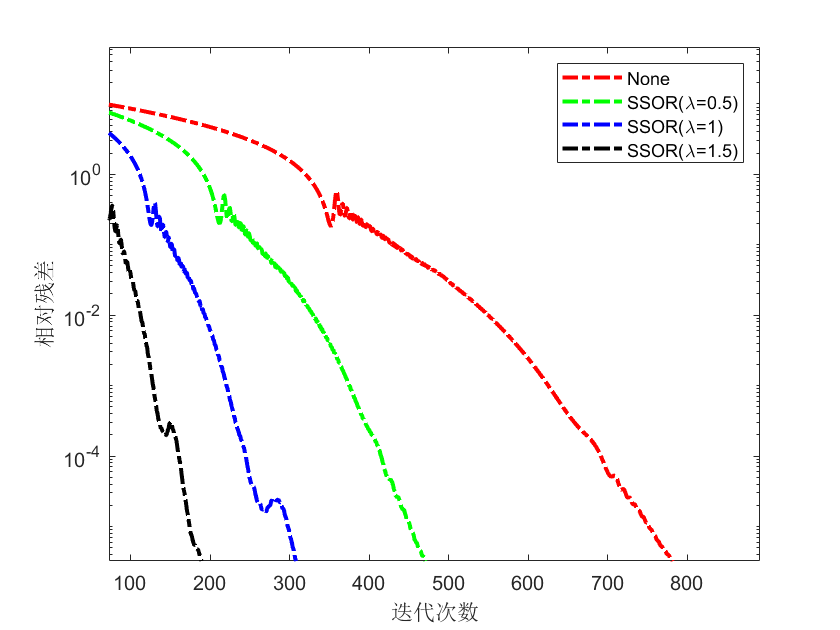

figure();
semilogy(0:iter1, resvec1/norm(b), 'r-.', 'LineWidth', 2);hold on;
semilogy(0:iter3, resvec3/norm(b), 'g-.', 'LineWidth', 2);
semilogy(0:iter2, resvec2/norm(b), 'b-.', 'LineWidth', 2);
semilogy(0:iter4, resvec4/norm(b), 'k-.', 'LineWidth', 2);
xlabel('迭代次数');
ylabel('相对残差');
legend('None', 'SSOR(\lambda=0.5)', 'SSOR(\lambda=1)', 'SSOR(\lambda=1.5)');

## 3. Conjugate Gradient Method with Incomplete Cholesky Factorization Preconditioner:

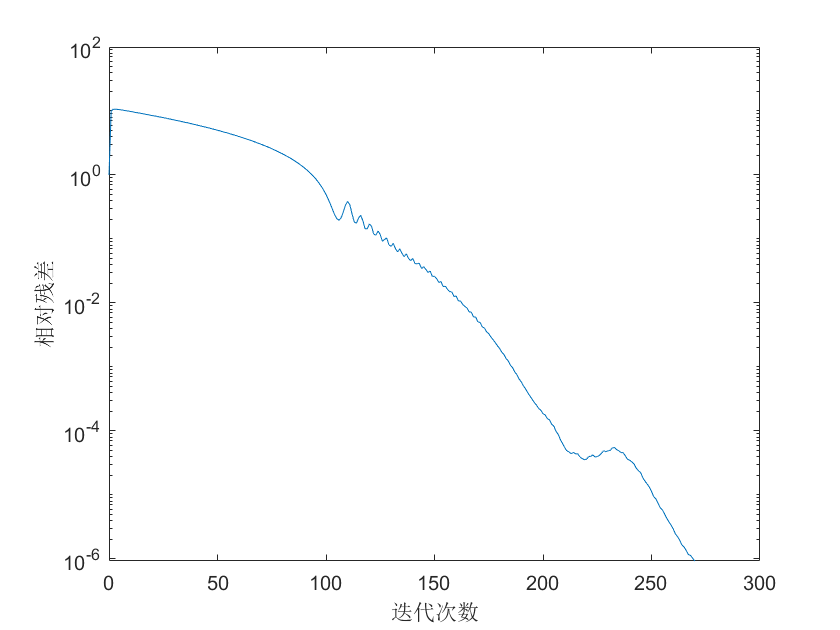

% IC-CG
L = ichol(A);
M = L * L';
[x5,relres5,iter5,resvec5] = my_pcg(A,b,tol,maxit,M,x_init);
clf;
semilogy(0:iter5, resvec5/norm(b));
xlabel('迭代次数');
ylabel('相对残差');

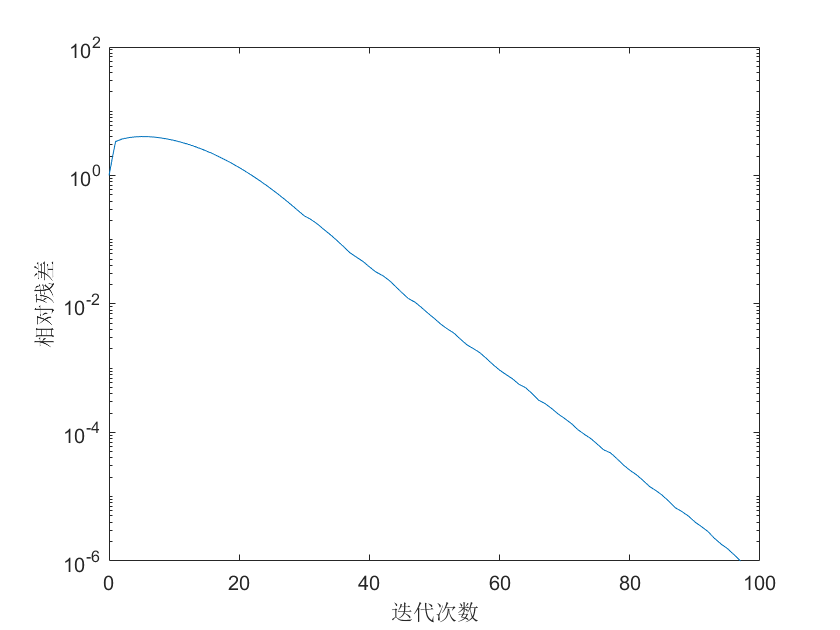

% Modified IC-CG
L = ichol(A,struct('michol','on'));
M = L * L';
[x6,relres6,iter6,resvec6] = my_pcg(A,b,tol,maxit,M,x_init);
clf;
semilogy(0:iter6, resvec6/norm(b));
xlabel('迭代次数');
ylabel('相对残差');

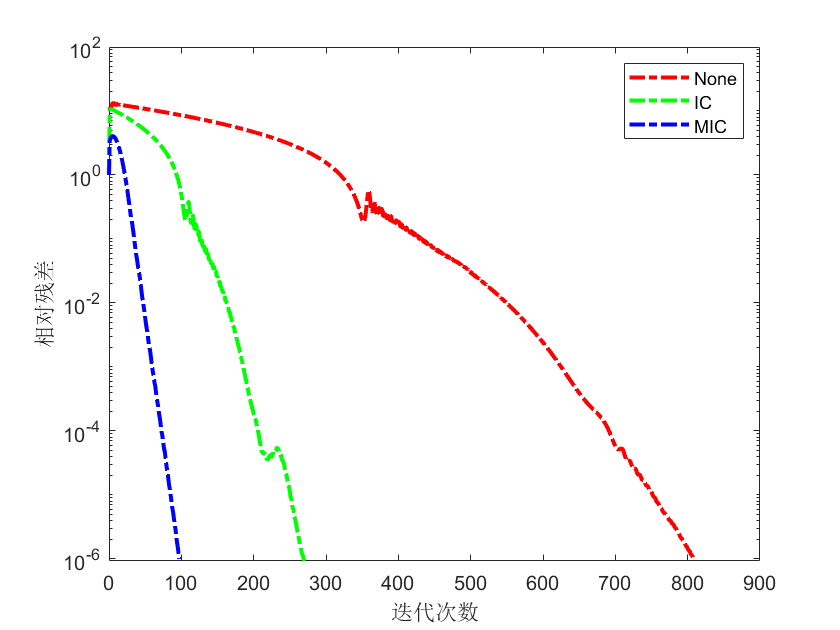

clf;
semilogy(0:iter0,resvec0./norm(b),'r-.','linewidth',2);
hold on;
semilogy(0:iter5,resvec5./norm(b),'g-.','linewidth',2);
semilogy(0:iter6,resvec6./norm(b),'b-.','linewidth',2);
xlabel('迭代次数');
ylabel('相对残差');
legend('None', 'IC', 'MIC');

% 通过阈值调降使用不完全 Cholesky 分解
L1 = ichol(A, struct('type','ict','droptol',1e-1));
[x7,fl7,rr7,it7,rv7] = pcg(A,b,tol,maxit,L1,L1');
L2 = ichol(A, struct('type','ict','droptol',1e-2));
[x8,fl8,rr8,it8,rv8] = pcg(A,b,tol,maxit,L2,L2');
L3 = ichol(A, struct('type','ict','droptol',1e-3));
[x9,fl9,rr9,it9,rv9] = pcg(A,b,tol,maxit,L3,L3'); 

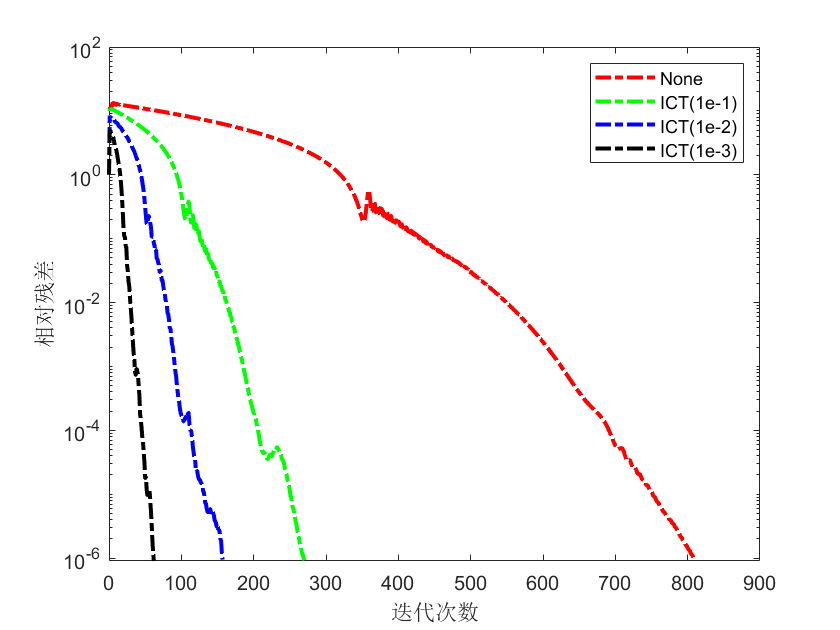


clf;
semilogy(0:iter0,resvec0./norm(b),'r-.','linewidth',2);
hold on;
semilogy(0:it7,rv7./norm(b),'g-.','linewidth',2);
semilogy(0:it8,rv8./norm(b),'b-.','linewidth',2);
semilogy(0:it9,rv9./norm(b),'k-.','linewidth',2);
xlabel('迭代次数');
ylabel('相对残差');
legend('None','ICT(1e-1)','ICT(1e-2)', 'ICT(1e-3)', 'Location', 'northeast');

methods = {'None'; 'Jacobi'; 'SSOR(0.5)'; 'SSOR(1.0)'; 'SSOR(1.5)'; 'IC'; 'MIC';'ICT(1e-1)'; 'ICT(1e-2)'; 'ICT(1e-3)'};
iteration_times = {iter0; iter1; iter3; iter2; iter4; iter5; iter6; it7; it8; it9};
table(methods, iteration_times)

ans = 10×2 table
      methods      iteration_times
    ___________    _______________

    'None'              [809]     
    'Jacobi'            [809]     
    'SSOR(0.5)'         [537]     
    'SSOR(1.0)'         [318]     
    'SSOR(1.5)'         [196]     
    'IC'                [270]     
    'MIC'               [ 97]     
    'ICT(1e-1)'         [270]     
    'ICT(1e-2)'         [157]     
    'ICT(1e-3)'         [ 62]     


methods = {'None'; 'Jacobi'; 'SSOR(0.5)'; 'SSOR(1.0)'; 'SSOR(1.5)'; 'IC'; 'MIC';'ICT(1e-1)'; 'ICT(1e-2)'; 'ICT(1e-3)'};
final_res = {resvec0(100); resvec1(100); resvec3(100); resvec2(100); resvec4(100); resvec5(100); resvec6(end); rv7(100); rv8(100); rv9(end)};
table(methods, final_res)   

ans = 10×2 table
      methods       final_res  
    ___________    ____________

    'None'         [4.2914e+03]
    'Jacobi'       [4.2914e+03]
    'SSOR(0.5)'    [2.9366e+03]
    'SSOR(1.0)'    [  938.1520]
    'SSOR(1.5)'    [   21.6821]
    'IC'           [  286.4503]
    'MIC'          [4.9721e-04]
    'ICT(1e-1)'    [  286.4503]
    'ICT(1e-2)'    [    0.0944]
    'ICT(1e-3)'    [4.5038e-04]
